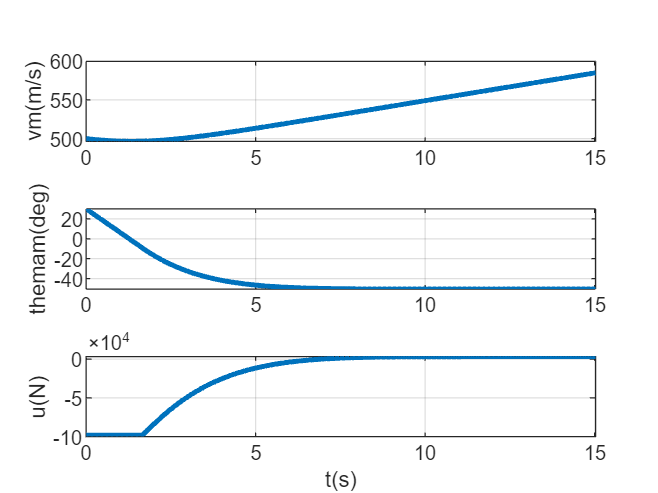

close all,clear,clc,
tic,

global m g rho S CQ vt
m = 500;
g = 9.8;
rho = 1.225;
S = 0.01;
CQ = 0.1;
vt = -72*1000/(60*60);

xm_initial = 0;
ym_initial = 5000;
vm_initial = 500;
thetam_initial = deg2rad(30);
xm = xm_initial;
ym = ym_initial;
vm = vm_initial;
thetam = thetam_initial;

xt_initial = 6000;%目标纵程初值
xt = xt_initial;
yt = 0;%地面目标
ytout = yt;

state = [xm; ym; vm; thetam; xt];
stateout = state;

q = -atan(ym/(xt-xm));
r = sqrt((xt-xm)^2+ym^2);
qdot = vm/r*sin(q-thetam)-vt/r*sin(q);
qout = q;
qdotout = qdot;
rout = r;
uout = [];

t = 0;
dt = 0.0005;
tout = t;

k = 10;%比例制导系数

while ym > 0
    u = k*m*vm*qdot + m*g*cos(thetam); %作为比例制导控制输入的导弹气动升力
    if abs(u/m) > 20*g %导弹过载限制
        u = sign(u)*20*m*g;
    end
    uout = [uout,u];
    
    ke1 = stateequation(t,state,u);
    ke2 = stateequation(t+0.5*dt,state+0.5*ke1*dt,u);
    ke3 = stateequation(t+0.5*dt,state+0.5*ke2*dt,u);
    ke4 = stateequation(t+dt,state+ke3*dt,u);
    state = state+1/6*(ke1+2*ke2+2*ke3+ke4)*dt;
    stateout = [stateout,state];
    
    xm = state(1);
    ym = state(2);
    vm = state(3);
    thetam = state(4);
    xt = state(5);
    
    q = -atan(ym/(xt - xm));
    r = sqrt((xt - xm)^2 + ym^2);
    qdot = vm/r*sin(q - thetam) - vt/r*sin(q);
    qout = [qout,q];
    rout = [rout,r];
    qdotout = [qdotout,qdot];
    
    t = t + dt;
    tout = [tout,t];
    
    yt = 0;
    ytout = [ytout,yt];
end

xmout = stateout(1,:);
ymout = stateout(2,:);
vmout = stateout(3,:);
thetamout = stateout(4,:);
xtout = stateout(5,:);
uout = [uout,uout(end)];

figure,
subplot(3,1,1),
plot(tout,vmout,'linewidth',2),
ylabel('vm(m/s)'),
grid on,

subplot(3,1,2),
plot(tout,thetamout*180/pi,'linewidth',2),
ylabel('themam(deg)'),
grid on,

subplot(3,1,3),
plot(tout,uout,'linewidth',2),
ylabel('u(N)'),
grid on,
xlabel('t(s)'),

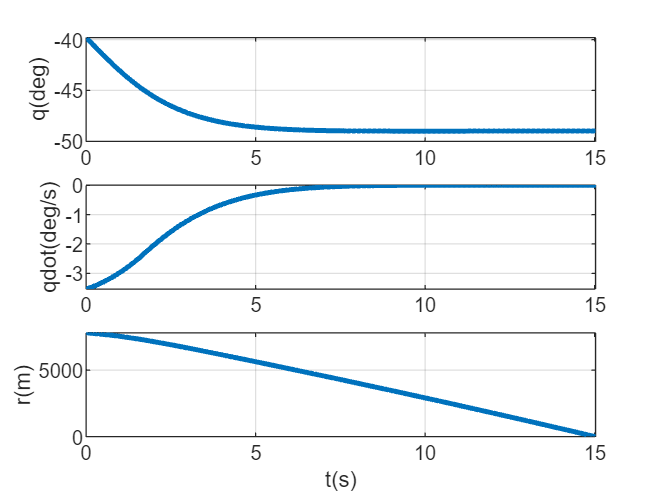


figure,
subplot(3,1,1),
plot(tout,qout*180/pi,'linewidth',2),
ylabel('q(deg)'),
grid on,

subplot(3,1,2),
plot(tout,qdotout*180/pi,'linewidth',2),
ylabel('qdot(deg/s)'),
grid on,

subplot(3,1,3),
plot(tout,rout,'linewidth',2),
ylabel('r(m)'),
xlabel('t(s)'),
grid on,


if r <= 1
    disp('脱靶量(m)'),
    r,
    disp('脱靶量小于误差范围，导弹命中目标，制导飞行试验圆满成功!'),
end

脱靶量(m)


r = 0.1976

脱靶量小于误差范围，导弹命中目标，制导飞行试验圆满成功!


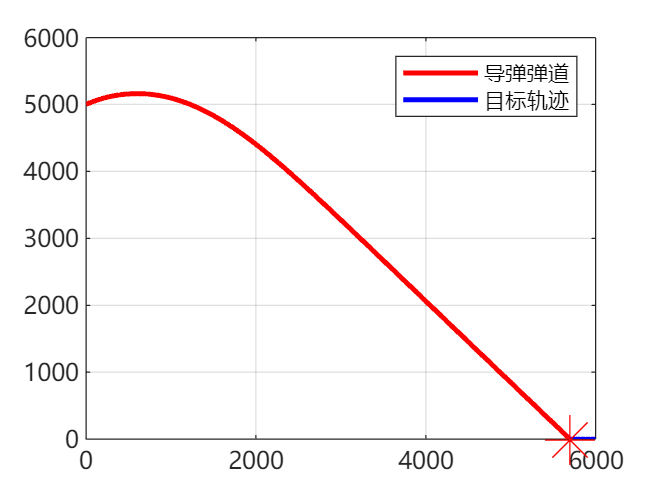


figure,
plot(xmout,ymout,'r','linewidth',2),
hold on,
plot(xtout,ytout,'b','linewidth',2)
hold on,
plot(xm,ym,'*r','markersize',20),
set(gca,'fontname','microsoft yahei'),
legend('导弹弹道','目标轨迹'),
grid on,


toc,

历时 8.121774 秒。


function statedot=stateequation(t,state,u)
global m g rho S CQ vt

xm = state(1);
ym = state(2);
vm = state(3);
thetam = state(4);
xt = state(5);

xmdot = vm*cos(thetam);
ymdot = vm*sin(thetam);
Q = 1/2*rho*vm^2*S*CQ;
vmdot = -g*sin(thetam)-Q/m;
Y = u; %导弹气动升力，在此就是制导控制输入量
thetamdot = -g/vm*cos(thetam)+Y/(m*vm);
xtdot = vt;

statedot=[xmdot; ymdot; vmdot; thetamdot; xtdot];
end